**INFORME TALLER 15**

** MATLAB**

**DIANA CAROLINA PINZÓN MOLINA**

**OLGA LUCIA QUINTERO MONTOYA**

DOCENTE

**UNIVERSIDAD EAFIT**

**ECUACIONES DIFERENCIALES**

**MEDELLÍN**

**2023-2**

** Modelo de un péndulo simple**

**Introducción **

En este taller, nos centramos en el estudio de un péndulo simple, un sistema físico compuesto por una masa suspendida de un punto fijo por una cuerda o barra. Nuestro objetivo principal es utilizar herramientas numéricas y computacionales para entender cómo se comporta este péndulo cuando se le aplica una fuerza no constante en el tiempo, como una fuerza tangencial que cambia con el movimiento. El taller se  trata de utilizar herramientas computacionales para comprender y explorar cómo se comporta un péndulo simple en respuesta a una fuerza que varía con el tiempo y cómo esta respuesta cambia cuando ajustamos diferentes parámetros del sistema. Esto nos proporcionará una comprensión más profunda de la dinámica del péndulo simple y de cómo se aplican métodos numéricos y de simulación en la resolución de problemas en la física y la ingeniería.

**Metodologia**

Para lograr esto, utilizaremos el método numérico de Runge-Kutta, que es una técnica matemática para aproximar soluciones de ecuaciones complicadas. En particular, aprovecharemos la función 'ode45' de MATLAB, que implementa este método de manera eficiente. Crearemos un archivo Live Script en MATLAB, que es un entorno interactivo que nos permitirá realizar cálculos y visualizar resultados de manera dinámica. A través de este archivo, introduciremos la ecuación de estado no lineal que describe el péndulo y utilizaremos 'ode45' para resolverla. Jugaremos con diferentes parámetros, como la longitud de la cuerda, la gravedad o la amplitud de la fuerza tangencial, y observaremos cómo estas variaciones afectan el movimiento del péndulo con el tiempo. Esto se hará mediante el análisis de la respuesta temporal, que nos mostrará cómo se desenvuelve el sistema con el tiempo, y el retrato de fase, que es una representación gráfica especial que nos ayudará a visualizar las trayectorias del péndulo en un espacio abstracto.

**Descripción del modelo**

                                   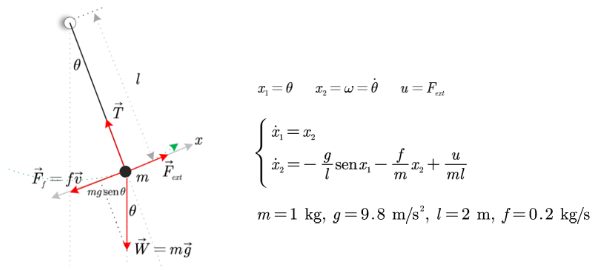

Donde, θ es el ángulo (en radianes, rad) respecto a la posición vertical, ω es la velocidad angular (en radianes por segundo, rad/s) y *u* es la fuerza externa aplicada tangencialmente. Los parámetros son la masa (*m*, en kilogramos), la longitud (*l*, en metros), la aceleración de la gravedad (*g*, en m/s2) y f es el coeficiente de fricción viscosa (*f*, N/(ms-1) o kg/s). Suposición: el hilo es rígido y tiene una masa que se puede despreciar, por lo que el péndulo puede tomar posiciones superiores.

1.  Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones temporales con una entrada u = 1. ¿Para que valor máximo de la entrada el sistema rotará indefinidamente?

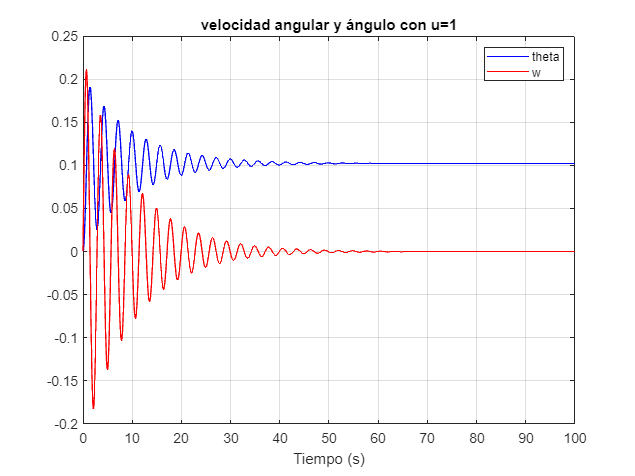

%solución del sistema con u=1
syms x1(t) x2(t)

m= 1;  %masa
g=9.8; %Aceleracion, gravedad
l=2;   %longitd del pendulo
f=0.2; %Coeficiente de friccion viscosa
u=1;   %Valor de u

f1 = x2;
f2 = (-g/l)*sin(x1)-(f/m)*x2+(u/(m*l));

%Parte derecha de la ecuación de estado de manera numérica
f = odeFunction([f1 f2],[x1 x2]);

h = 0.1;
%tiempo simulacion
tmin = 0;
tmax = 100;
tspan = tmin:h:tmax;

ci = [0 0]; 
[t,x] = ode45(f,tspan,ci);
%solucion para theta
theta = x(:,1);
w = x(:,2);
%grafica
figure
plot(t,theta,'b',t,w,'r'),
xlabel('Tiempo (s)');
legend('theta','w')
grid on
title ("velocidad angular y ángulo con u=1")

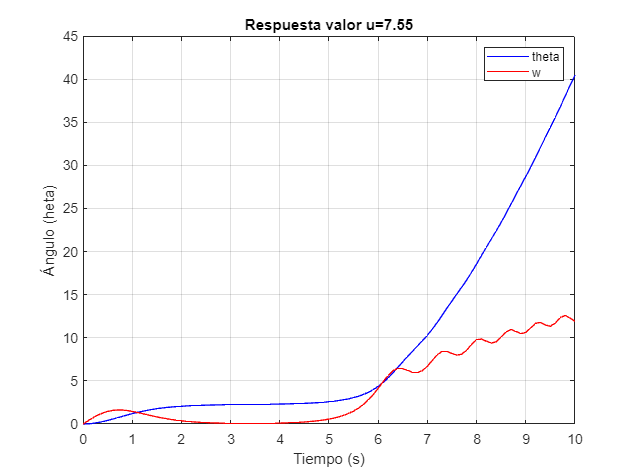

%solución del sistema con u=7.55 (valor donde el sistema rotará) indefinidamente
syms x1(t) x2(t)
%paametros
m= 1; 
g=9.8; 
l=2; 
f=0.2; 
u=7.55;

f1 = x2;
f2 = (-g/l)*sin(x1)-(f/m)*x2+(u/(m*l));


f = odeFunction([f1 f2],[x1 x2]);

h1 = 0.1;



ci = [0 0]; 
[t,x] = ode45(f,tspan,ci);

theta = x(:,1);

w = x(:,2);

figure
plot(t,theta,'b',t,w,'r'),
xlabel('Tiempo (s)');
ylabel('Ángulo (heta)');
legend('theta','w')
title ("Respuesta valor u=7.55")
grid on

2. Trazar la curva de linealidad, es decir, el valor en el que se estabiliza el péndulo en función del valor de la entrada. El rango de entradas no debe superar el valor máximo calculado anteriormente.

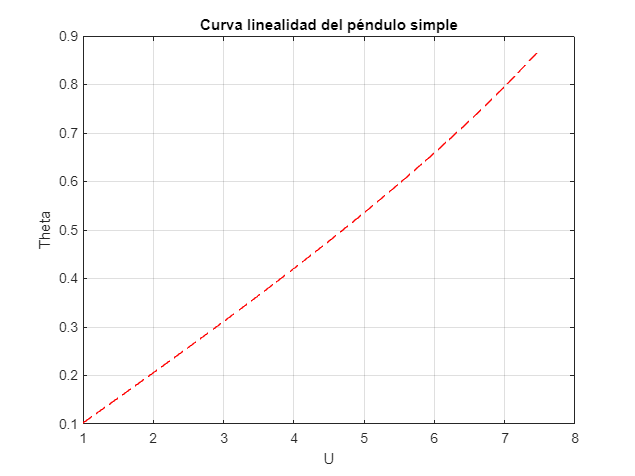

%Analizar el sistema al cambiar los valores de u

syms x1(t) x2(t)

m= 1; g=9.8; l=2; f=0.2; 

u=1:0.5:7.55;

sol2=[];

for i=1: numel(u)

    U=u(i);
    F1= x2;
    F2 = (-g/l)*sin(x1)-(f/m)*x2+(U/(m*l));

    F =odeFunction ([F1 F2], [x1 x2]);

    h=0.01;
    
    tspan=0:h:100;

    ci=[0 0];

    [t,sol2{i}]= ode45(F, tspan, ci);

    theta(i) = sol2{i}(end,1);
     
end
figure
plot (u,theta, 'r--');
xlabel ('U');
ylabel ('Theta');
title ("Curva linealidad del péndulo simple")
grid on 

3. Dibujar el retrato de fase para un cambio en la condición inicial de la velocidad angular entre 3 y 6 rad/s con incrementos de 0.5 rad/s. Interpretar el resultado. ¿Para qué valor de la frecuencia angular inicial el péndulo da una vuelta? ¿Para qué valor da tres vueltas? Observar los puntos de equilibrio.

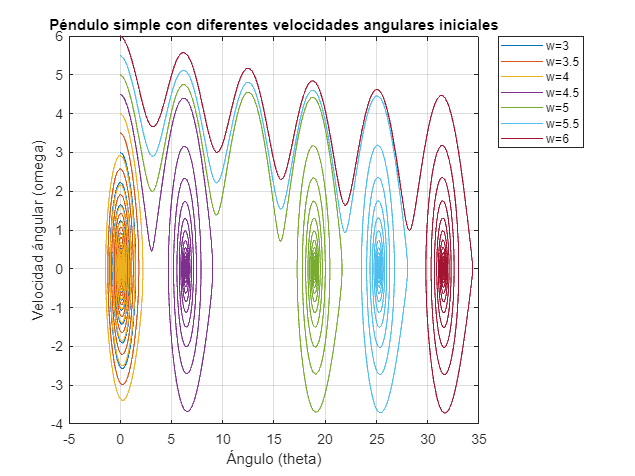

%Analizar el sistema al cambiar los valores de w

m= 1; g=9.8; l=2; f=0.2; u=1;

w0=3:0.5:6;


for i=1: numel(w0)

   syms x1(t) x2(t)

    F1= x2;
    F2 = (-g/l)*sin(x1)-(f/m)*x2+(u/(m*l));

    F =odeFunction ([F1 F2], [x1 x2]);

    h=0.01;
    
    tspan=0:h:100;

    ci=[0 w0(i)];

    [t,sol]= ode45(F, tspan, ci);

    theta = sol(:,1);
     w = sol(:,2);

    plot (theta,w);
hold on
     
end

hold off

legend ('w=3','w=3.5','w=4', 'w=4.5','w=5','w=5.5','w=6',"Location","northeastoutside")
xlabel ("Ángulo (theta)")
ylabel ("Velocidad ángular (omega)")
title ("Péndulo simple con diferentes velocidades angulares iniciales")
grid on 

`4. `Dibujar el retrato de fase para un cambio en la condición inicial de la posición angular entre -6 y 6 rad con incrementos de 0.5 rad. Interpretar el resultado. Observar los tres únicos puntos de equilibrio.

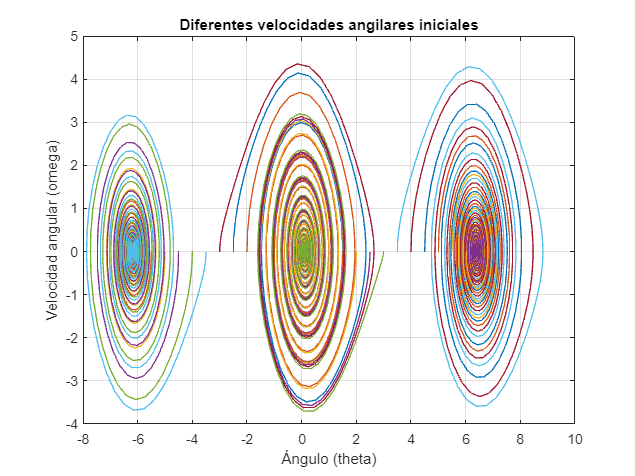

%Analizar el sistema al cambiar los valores de w

m= 1; g=9.8; l=2; f=0.2; u=1;

teta0=-6:0.5:6;


for i=1: numel(teta0)

   syms x1(t) x2(t)

    F1= x2;
    F2 = (-g/l)*sin(x1)-(f/m)*x2+(u/(m*l));

    F =odeFunction ([F1 F2], [x1 x2]);

    h=0.1;
    
    tspan=0:h:500;

    ci=[teta0(i) 0];

    [t,sol]= ode45(F, tspan, ci);

     w = sol(:,1);
     teta = sol(:,2);

    plot (w,teta);
  hold on 
     
end
xlabel ("Ángulo (theta)")
ylabel ("Velocidad angular (omega)")
title ("Diferentes velocidades angilares iniciales")
grid on
hold off

5. Explicar el efecto del cambio de la longitud del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

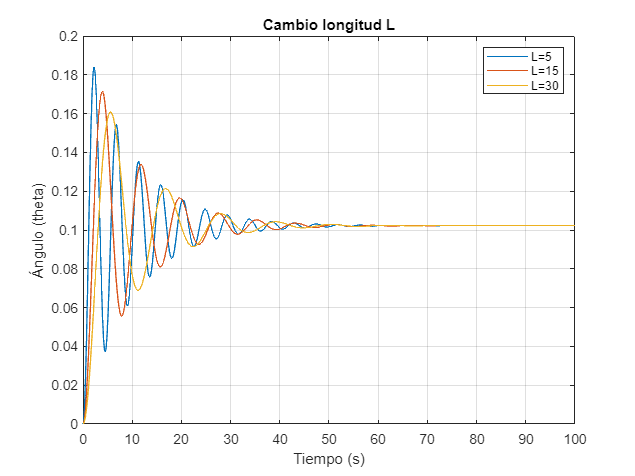

syms x1(t) x2(t)

m= 1; g=9.8; u=1; f=0.2; 

l= [5 15 30];

sol5=[];

for i=1: numel(l)

    L=l(i);
    F1= x2;
    F2 = (-g/L)*sin(x1)-(f/m)*x2+(u/(m*L));

    F =odeFunction ([F1 F2], [x1 x2]);

    h=0.1;
    
    tspan=0:h:100;

    ci=[0 0];

    [t1,sol5]= ode45(F, tspan, ci);

    theta = sol5(:,1);

    plot (t1,theta);
    xlabel ('tiempo');
    ylabel ('Theta');
    hold on
    
end
legend ('L=5','L=15','L=30')
xlabel ("Tiempo (s)")
ylabel ("Ángulo (theta)")
title ("Cambio longitud L")
grid on
hold off

6. Explicar el efecto del cambio de la masa del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

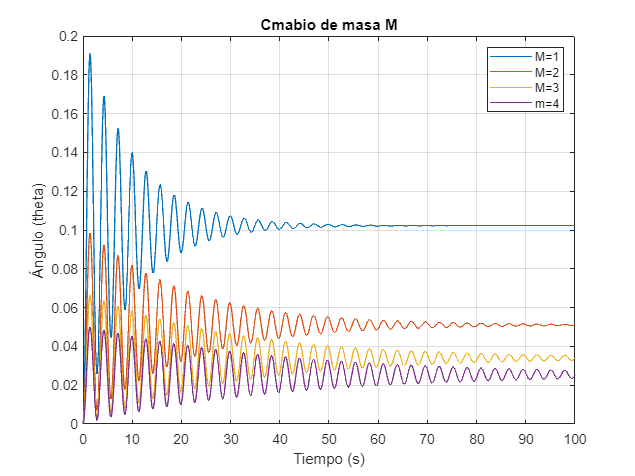


syms x1(t) x2(t)

l= 2; g=9.8; u=1; f=0.2; 

m= [1 2 3 4 ];

sol=[];

for i=1: numel(m)

    M=m(i);
    F1= x2;
    F2 = (-g/l)*sin(x1)-(f/M)*x2+(u/(M*l));

    F =odeFunction ([F1 F2], [x1 x2]);

    h=0.1;
    
    tspan=0:h:100;

    ci=[0 0];

    [t1,sol]= ode45(F, tspan, ci);

    theta = sol(:,1);

    plot (t1,theta);
    xlabel ('tiempo');
    ylabel ('Theta');
    hold on
         
end

legend ('M=1','M=2','M=3',"m=4")
xlabel ("Tiempo (s)")
ylabel ("Ángulo (theta)")
title ("Cmabio de masa M")
grid on
hold off

7. Explicar el efecto del cambio de la fricción viscosa del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

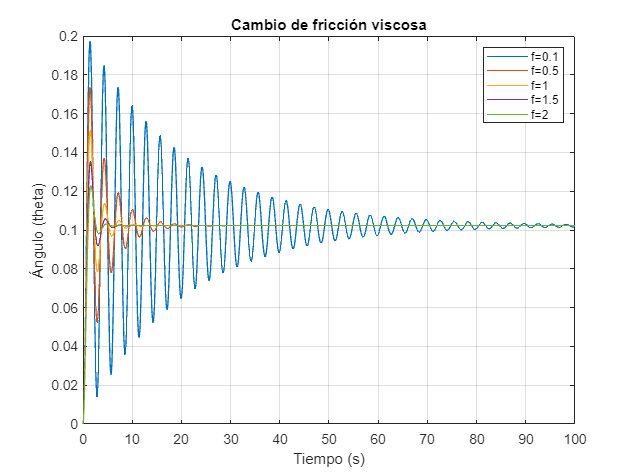

syms x1(t) x2(t)

l= 2; g=9.8; u=1; m=1; 

f= [0.1 0.5 1 1.5 2];

sol=[];

for i=1: numel(f)

    f(i);
    F1= x2;
    F2 = (-g/l)*sin(x1)-(f(i)/m)*x2+(u/(m*l));

    F =odeFunction ([F1 F2], [x1 x2]);

    h=0.1;
    
    tspan=0:h:100;

    ci=[0 0];

    [t1,sol]= ode45(F, tspan, ci);

    theta = sol(:,1);

    plot (t1,theta);
    xlabel ('tiempo');
    ylabel ('Theta');
    hold on
     
end

legend ('f=0.1','f=0.5','f=1', "f=1.5", "f=2")
xlabel ("Tiempo (s)")
ylabel ("Ángulo (theta)")
title("Cambio de fricción viscosa")
grid on
hold off

8. Si f = 0, u = 0 (movimiento libre no amortiguado) y la posición angular inicial ω(0) es menor a unos 30° (0.5 radianes, aproximadamente), se puede aproximar el seno del ángulo en radianes por el ángulo (comprobar con la calculadora o MATLAB) y el modelo es lineal. Obtener la ecuación de estado, pasar a la ecuación diferencial homogénea con coeficientes constantes y resolverla analíticamente. ¿Cómo se puede medir la aceleración de la gravedad si se conoce la longitud? ¿Cómo se puede obtener la longitud si se conoce la aceleración de la gravedad? Comprobar los resultados con MATLAB

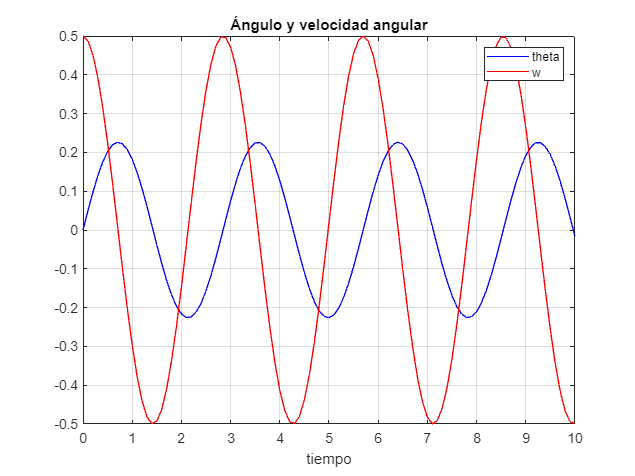

syms x1(t) x2(t)

m= 1; g=9.8; l=2; f=0; u=0;

f1 = x2;
f2 = (-g/l)*sin(x1)-(f/m)*x2+(u/(m*l));


f = odeFunction([f1 f2],[x1 x2]);

h = 0.1;

tmin = 0;
tmax = 10;
tspan = tmin:h:tmax;

ci = [0 0.5]; 
[t,x] = ode45(f,tspan,ci);

theta = x(:,1);
w = x(:,2);

figure
plot(t,theta,'b',t,w,'r'),
xlabel('tiempo'),
legend('theta','w')
title ("Ángulo y velocidad angular")
grid on

9. Si se conoce la respuesta temporal de un péndulo con fuerza igual a 1 N, *l* = 2 y *g* = 9.8, hallar aproximadamente por tanteo los valores de *f* y *m*. Explicar el procedimiento. Tener en cuenta los resultados de las tareas 6 y 7.

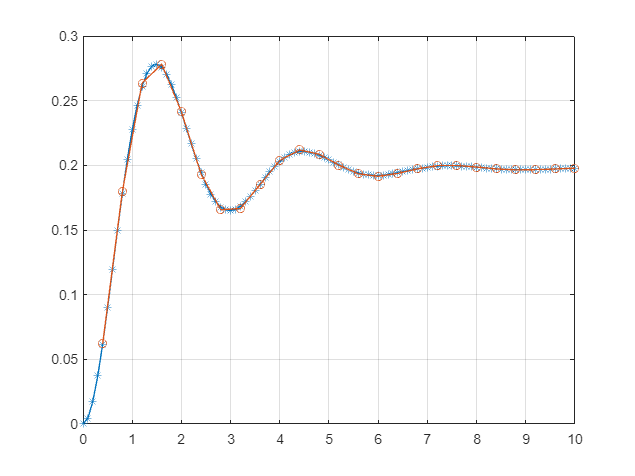


t9 = [0.4 0.8 1.2 1.6 2 2.4 2.8 3.2 3.6 4 4.4 4.8 5.2 5.6 6 6.4 6.8 7.2 7.6 8 8.4 8.8 9.2 9.6 10];

ang= [0.0621 0.1797 0.2635 0.2783 0.2414 0.1932 0.1656 0.1667 0.1852 0.2038 0.2119 0.2086 0.2002 0.1934 0.1915 0.1938 0.1973 0.1997 0.1999 0.1987 0.1972 0.1965 0.1966 0.1972 0.1978];

m= 0.52; 
f= 0.63; 
g= 9.8; 
l= 2; 
u = 1; 

     syms x1(t) x2(t)  

     f1 = x2;  
     f2 = -((g/l)*sin(x1))-((f/m)*x2)+(u/(m*l));

     F = odeFunction([f1 f2],[x1 x2]);  

     h = 0.1; 

    tmin = 0;
    tmax = 10;
    tspan = tmin:h:tmax; 

    ci = [0 0]; 

    [t,sol] = ode45(F,tspan,ci); 

    teta = sol(:,1); 

figure   
plot(t,teta,'*-')
hold on
plot(t9,ang,'o-')
hold off
grid on

10. Montar un experimento en casa de un péndulo con entrada igual cero y un ángulo inicial entre 20 y 60°, y hallar los parámetros *l* y *f* si se conocen *m* y *g*. Es decir, suponer que no se sabe la longitud. Al final, mostrar la discrepancia de la longitud. ¿Por qué si no hay entrada el experimento no sirve para hallar *f* y *m* como en la tarea anterior?

**Análisis de resultados**

**1. **A partir del análisis de la gráfica generada, es posible extraer una conclusión fundamental: para que el péndulo pueda realizar una rotación completa indefinidamente, es decir, completar un giro de 360 grados, se requiere aplicar una fuerza mínima de 7.55 Newtons (N). Esta información resulta esencial, ya que nos indica el umbral de fuerza necesario para mantener el péndulo en movimiento constante, superando la resistencia de la gravedad y cualquier fricción presente en el sistema.

**2. **Al examinar detenidamente la gráfica proporcionada, se hace evidente que existe una relación directa entre la fuerza aplicada en el péndulo y el ángulo de desviación del mismo. Por esto se puede decir que  que a medida que incrementamos los valores de entrada de la fuerza ejercida sobre el péndulo, se observa un aumento coincidente en los valores del ángulo de desviación del péndulo.

Este patrón de comportamiento revela una conexión  entre la magnitud de la fuerza aplicada y la amplitud de oscilación del péndulo. Cuanto mayor es la fuerza ejercida, mayor es la magnitud del ángulo que el péndulo alcanza en su movimiento. Este fenómeno puede interpretarse como una manifestación directa de la influencia de la fuerza externa sobre el sistema del péndulo simple.

**3. **En la observación de este escenario particular, se destaca que, en función de condiciones iniciales específicas de 4.5 y 5 grados de ángulo de desviación, el péndulo manifiesta un comportamiento notablemente distintivo. Cuando el péndulo se inicia con una desviación angular de 4.5 grados, es notablese puede ver que completa una única rotación completa. Sin embargo, en el segundo caso, cuando las condiciones iniciales establecen un ángulo de 5 grados, el péndulo no se limita a una sola rotación, sino que ejecuta tres vueltas completas consecutivas.

Esta observación hace énfasis la importancia crítica de las condiciones iniciales en la determinación del comportamiento del péndulo. Pequeñas variaciones en el ángulo inicial de desviación pueden desencadenar resultados diferentes. De manera igualmente, resalta la flexibilidad del péndulo para mostrar dierentes comportamientos cuando se proporcionan las condiciones adecuadas.

Este hallazgo resalta la sensibilidad de los sistemas físicos a sus condiciones iniciales y resalta la variabilidad del péndulo de tener resultados diferentes y notables. Esta comprensión es fundamental en la física y la ingeniería, donde la predicción y el control de sistemas dinámicos dependen en gran medida de la consideración y manipulación de dichas condiciones iniciales.

**4. **

**a. Para condiciones iniciales entre -8 y -3.5 grados:** se puede identificar un punto de equilibrio en -6. Esto significa que cuando el péndulo se inicia con un ángulo de desviación en este rango, su movimiento eventualmente se estabilizará en una posición en la cual se encuentra a -6 grados de desviación respecto a la vertical. Este resultado destaca la tendencia del péndulo a establecer una posición de equilibrio en respuesta a condiciones iniciales específicas.

**b. Para condiciones iniciales entre -3 y 3 grados:** el punto de equilibrio se ubica en 0. Esto implica que, cuando el péndulo se inicia con un ángulo de desviación en este intervalo, el sistema logra mantenerse en un equilibrio perfecto, es decir, el péndulo oscila alrededor de la posición vertical sin alejarse de ella. Esta es una situación muestra cómo el sistema puede permanecer en equilibrio sin importar la perturbación inicial.

**c. Para condiciones iniciales entre 3.5 y 9 grados:** se identifica un punto de equilibrio en 6.3. En este caso, cuando el péndulo se inicia con un ángulo de desviación en este rango, se estabiliza en una posición que se encuentra a 6.3 grados de desviación respecto a la vertical. Esto revela que las condiciones iniciales específicas en este intervalo conducen a un equilibrio en una posición inclinada, diferente de la vertical.

Este punto resalta cómo el sistema del péndulo responde de manera distintiva a diferentes condiciones iniciales, lo que  demuestra la importancia de la elección de condiciones iniciales en la comprensión y predicción de su comportamiento. Además, esta grafica refuerza la idea de que el péndulo simple es un sistema dinámico que puede adoptar múltiples configuraciones de equilibrio en función de su estado inicial. 

**5. **De esta grafica se puede decir que, sin importar la longitud de la cuerda utilizada, el péndulo alcanza un valor de equilibrio en un período de tiempo constante. Sin embargo, a pesar de esta constancia en el tiempo requerido para llegar a una posición de equilibrio, observamos una variación significativa en el número de oscilaciones que el péndulo realiza antes de llegar a ese estado estabilizado. Este fenómeno plantea cuestiones importantes sobre el comportamiento del péndulo. La estabilización en el mismo valor en un período constante sugiere que el péndulo se ajusta gradualmente a una posición de equilibrio bajo la influencia de factores como la gravedad y la resistencia del aire. Esta adaptación hacia una posición estable es independiente de la longitud de la cuerda y está intrínsecamente relacionada con las características fundamentales del sistema. Por otro lado, la variación en el número de oscilaciones antes de alcanzar el equilibrio nos lleva a explorar la variedad de comportamientos que el péndulo puede tener. La longitud de la cuerda afecta la amplitud y la frecuencia de las oscilaciones, lo que, a su vez, influye en el número total de oscilaciones antes de que el sistema alcance una posición de equilibrio. Esto resalta la importancia de considerar múltiples variables y parámetros al analizar sistemas dinámicos, ya que pequeños cambios en estos factores pueden tener un impacto en el comportamiento general del sistema. En resumen, esta observación muestra cómo, en el estudio de sistemas como el péndulo, es esencial considerar tanto los aspectos constantes como las variables que influyen en su dinámica, lo que nos lleva a una comprensión más completa de su comportamiento. 

**6. **Se puede ver que a medida que incrementamos la masa del péndulo, se presenta un patrón en su comportamiento. Con el aumento de la masa, notamos que el tiempo necesario para que el péndulo alcance una posición de equilibrio se extiende, es decir, el sistema tarda más en estabilizarse. Además, en relación con este aumento del tiempo de equilibrio, el valor donde finalmente se equilibra el péndulo disminuye progresivamente. Podemos decir entonces que, el incremento de la masa implica una mayor inercia del sistema, lo que, a su vez, demanda más tiempo para que la gravedad y otras fuerzas relevantes logren contrarrestar la desviación inicial del péndulo y lo lleven a una posición de equilibrio. Esta extensión en el tiempo de estabilización es un indicio del papel de la inercia en la dinámica del péndulo. Este cambio demuestra cómo la masa desempeña un papel fundamental en la respuesta del péndulo y cómo su variación puede influir en aspectos cruciales de su comportamiento, como el tiempo de estabilización y el ángulo de equilibrio.

**7. **Se evidencia una relación notable entre el número de oscilaciones del péndulo y la fricción viscosa. A medida que el valor de la fricción viscosa se incrementa, se produce una disminución en el número de oscilaciones que el péndulo puede llevar a cabo antes de alcanzar su estado de equilibrio. Sin embargo, es importante destacar que, a pesar de esta variación en el número de oscilaciones, el péndulo aún se estabiliza en el mismo valor final. Esto revela una conexión fundamental entre la fricción viscosa y la capacidad del péndulo para mantener sus oscilaciones. La fricción viscosa actúa como una fuerza que disipa gradualmente la energía del sistema, lo que resulta en una reducción en la amplitud y la duración de las oscilaciones del péndulo. A medida que esta fuerza disipativa se vuelve más grande, las oscilaciones se vuelven menos prominentes y el péndulo se estabiliza más rápidamente. Sin embargo, es importante notar que, a pesar de esta disminución en el número de oscilaciones, el péndulo aún alcanza la misma posición de equilibrio final. Esto nos dice que, aunque la fricción viscosa afecta la dinámica del péndulo al reducir su capacidad para oscilar, no altera la posición de equilibrio a la que el péndulo tiende a estabilizarse. En otras palabras, la fricción viscosa modifica la amplitud y la duración de las oscilaciones, pero no cambia la posición final de equilibrio.

**8. **

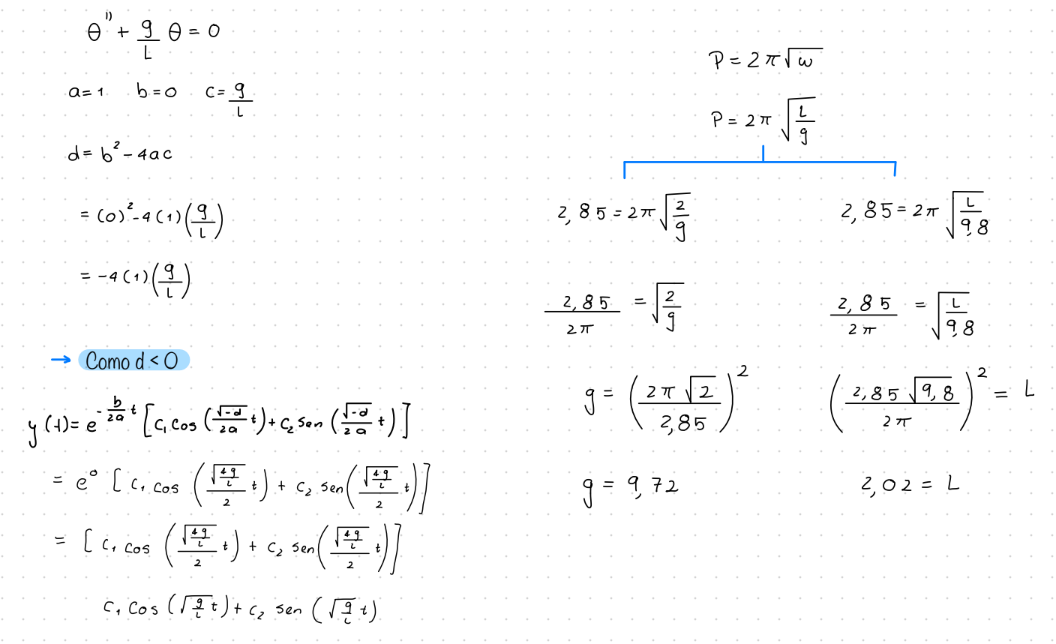

**9. **En el análisis, se identifica que los valores críticos de masa y fricción viscosa para que el péndulo se comporte de acuerdo con el modelo propuesto son de 0.52 y 0.63, respectivamente. Estos valores son fundamentales en la definición del comportamiento deseado del péndulo, lo que nos permite establecer las condiciones precisas en las cuales el sistema sigue el modelo teórico de referencia. Para llegar a estos valores, se realizo un proceso de tanteo. En el caso de la masa, se observo que al reducir la masa del péndulo, la amplitud de las oscilaciones aumentaba, hasta que alcanzó un punto crítico en 0.52, donde el péndulo exhibía la amplitud de oscilación prevista en el modelo. Esta observación llevó a la conclusión de que una masa de 0.52 era necesaria para replicar el comportamiento del modelo en términos de amplitud. Por otro lado, en relación a la fricción viscosa, se estudio detenidamente su efecto en el comportamiento del péndulo. En el numeral 7 del análisis, a medida que el coeficiente de fricción viscosa aumentaba, las oscilaciones del péndulo disminuían progresivamente. Esto  permitió identificar el valor crítico de 0.63, en el cual el péndulo presentaba el tipo de oscilaciones y atenuación previstos en el modelo.

**10.** Videos del experimento hecho en clase en teams

Para el experimento, se tienen los siguientes valores:

m=520.3g

theta0=30°

tiempo en parar =11:15m

El periodo T medido fue de 1.74s aproximadamente, para hallar la longitud se hace la siguiente formula $T=2\pi \sqrt{\frac{1}{g}}\to L=\frac{g\;T^2 }{4\pi }$  y para la fuerza respectivamente se usa $f=4m\pi T$

L = (9.8*(1.20)^2)/(4*pi)

L = 1.1230

f = (4*0.5203*pi*1.20)

f = 7.8459

La longitud estimada del péndulo en centímetros es de 112 cm, pero la longitud real de la cuerda es de 85 cm. Esto genera una diferencia de 27 cm, que podría deberse a errores de medición o factores no considerados en el modelo.

Cuando no aplicamos ninguna fuerza de entrada, la fricción viscosa hace que la amplitud de las oscilaciones disminuya con el tiempo, lo que finalmente lleva al péndulo a detenerse.